# Vector Demo

A notation convention

- Scalars are lower case: `x`

- Vectors (1-D arrays) are double letters: `xx`

- Matrices (2-D arrays) are capitals: `X`

## Creation

As an vector with step size = 1

xx = 1:5

xx =      1     2     3     4     5


size(xx)

ans =      1     5


As a list with step size ~= 1

yy = 1:3:10

yy =      1     4     7    10


As an N-by-1 column of zeros

zz = zeros(5,1)

zz =      0
     0
     0
     0
     0


zz = zeros(5)

zz =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


As a 1-by-N row of ones

oo  = ones(1,5)

oo =      1     1     1     1     1


ff = 5*ones(1,5)

ff =      5     5     5     5     5


A vector (1-by-N row) of psuedorandom numbers

rr = rand(1,5)

rr =     0.8147    0.9058    0.1270    0.9134    0.6324


Manually, as a row vector, with and without commas.

mm = [5 3.1 9.8 -2]

mm =     5.0000    3.1000    9.8000   -2.0000



nn = [5, 3.1, 9.8, -2]

nn =     5.0000    3.1000    9.8000   -2.0000


Manually as a column vector

cc = [5; 
    3.1; 
    9.8; 
    -2;]

cc =     5.0000
    3.1000
    9.8000
   -2.0000


% As a column using transpose
dd = [5 3.1 9.8 -2]'

dd =     5.0000
    3.1000
    9.8000
   -2.0000


Linear spacing from A to B with N elements

ll = linspace(0, 1, 5)

ll =          0    0.2500    0.5000    0.7500    1.0000


mm = 0:0.5:1

mm =          0    0.5000    1.0000


Logrithmic spacing from 10^A to 10^B with N elements

pp = logspace(-2, 2, 5)

pp =     0.0100    0.1000    1.0000   10.0000  100.0000


### Exercises

Find a comand to create the following vectors

42*ones(1,4)

ans =     42    42    42    42


42*[1 1 1 1 
    ]

ans =     42    42    42    42


4:-2:-4

ans =      4     2     0    -2    -4


linspace(4,-4,5)

ans =      4     2     0    -2    -4


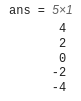

linspace(4,-4,5)'

ans =      4
     2
     0
    -2
    -4


## Indexing and Slicing

Given a vector...

aa = 10:10:100

aa =     10    20    30    40    50    60    70    80    90   100


Access an element by its index

aa(3)

ans = 30

Slice a vector with a vector of indices

aa(1:3)

ans =     10    20    30


aa(8:end)

ans =     80    90   100


aa(end-3:end)

ans =     70    80    90   100


aa([3 5 7])

ans =     30    50    70


Modifying an element

aa(3) = 0

aa =     10    20     0    40    50    60    70    80    90   100


 or elements

aa([1 5]) = -1

aa =     -1    20     0    40    -1    60    70    80    90   100


aa([2 4]) = [-2 -3]

aa =     -1    -2     0    -3    -1    60    70    80    90   100


### Exercises

Given `bb`, extact all the elements in odd-numberd positions.

bb = 1:9

bb =      1     2     3     4     5     6     7     8     9


b_slice = bb([1,3,5,7])

b_slice =      1     3     5     7


bb

bb =      1     2     3     4     5     6     7     8     9



bb([1,3,5,7]) = -1

bb =     -1     2    -1     4    -1     6    -1     8     9


Given `cc` , using indexing create a new vector that reverses the order of the elements

cc = [5 10 15 20]

cc =      5    10    15    20


size(cc,2)

ans = 4

c_rev = [];
for ii = 1:size(cc, 2)
    disp(cc(ii))
end

     5
    10
    15
    20



c_rev = [cc(end) cc(end-1) cc(end-2)]

c_rev =     20    15    10


c_ref = cc(end:-1:1)

c_ref =     20    15    10     5


Given `dd`, **find** the index of the elements with value equal to -1.0

dd = sin((0:7) * pi / 2)

dd =          0    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000


**find** the indices for all the elements of `dd `wtih value equal to 1.0

## Array vs Matrix Operations

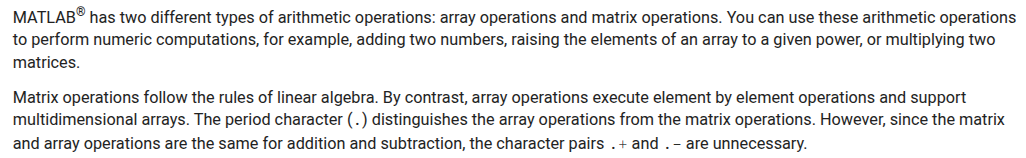

[Link](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html)

For now we want to use only element-wise array operations by prepending the math symbol with a period.

aa = [1 2]

aa =      1     2


Addition/Subtraction

bb = aa+10

bb =     11    12


cc = aa-bb

cc =    -10   -10


Multiplication/Division

Multiply by a scalar

dd = aa*0.1

dd =     0.1000    0.2000


Element-wise multiplication

dd

dd =     0.1000    0.2000


aa

aa =      1     2


ee = dd.*aa

ee =     0.1000    0.4000


but this throws an errror!

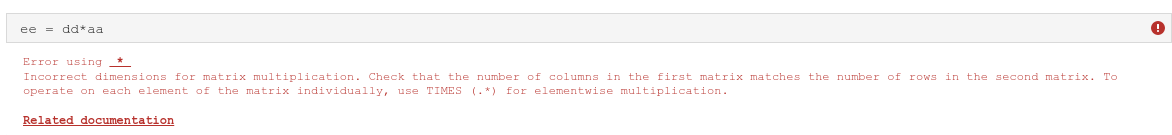

dd = ee./aa

dd =     0.1000    0.2000


Exponents

Scalar exponent

ff = [1 2 4];
gg = ff.^2

gg =      1     4    16


Element-wise exponent

gg = [-1 1 -1];
hh = ff.^gg

hh =     1.0000    2.0000    0.2500


but this throws an errror!